# Lecture #7 Notes

# Introduction to Clustering and k-means clustering                                 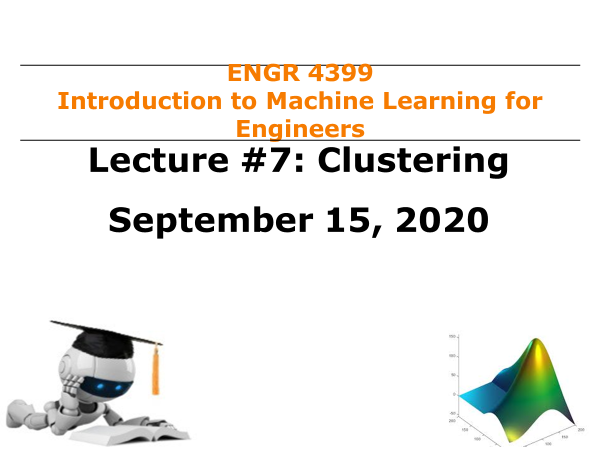

## Process to Develop Machine Learning Algorithms

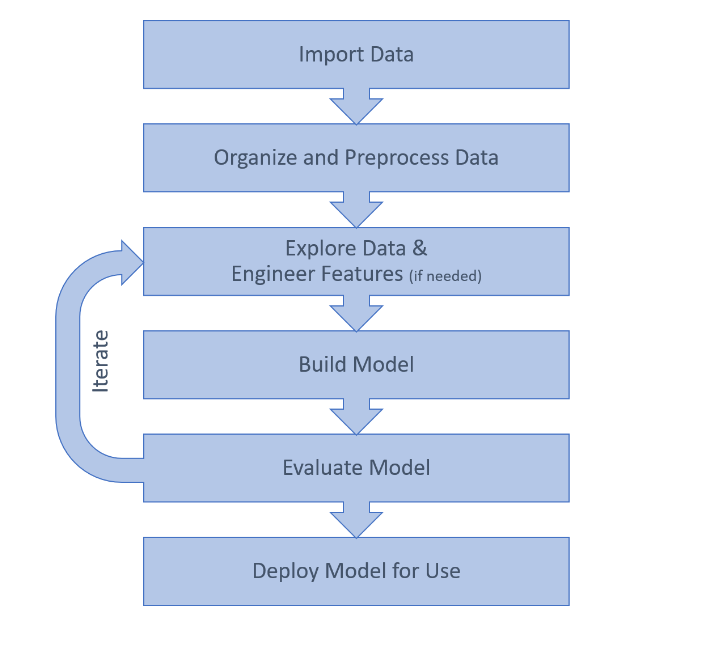

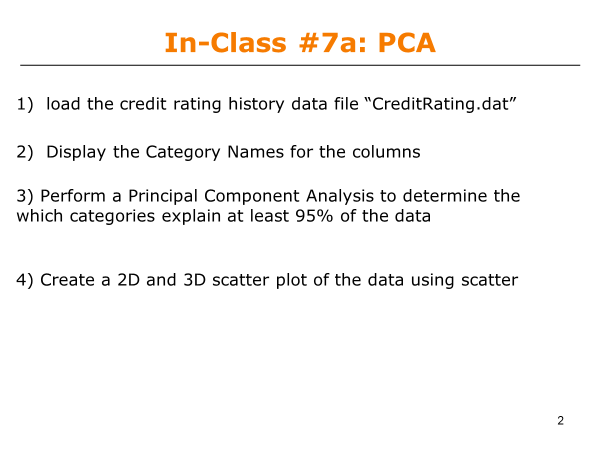

creditrating = readtable('CreditRating.dat');
creditrating.Properties.VariableNames
creditrating(1:5,:)
X = creditrating{:,2:7}; %convert from Table to Numerical, note curly brackets!
X1 = table2array(creditrating(:,2:7)) %another way to get numerical data from Table
[pcs,scrs,~,~,pexp] = pca(X);
pareto(pexp)
scatter(scrs(:,1),scrs(:,2))
scatter3(scrs(:,1),scrs(:,2),scrs(:,3))



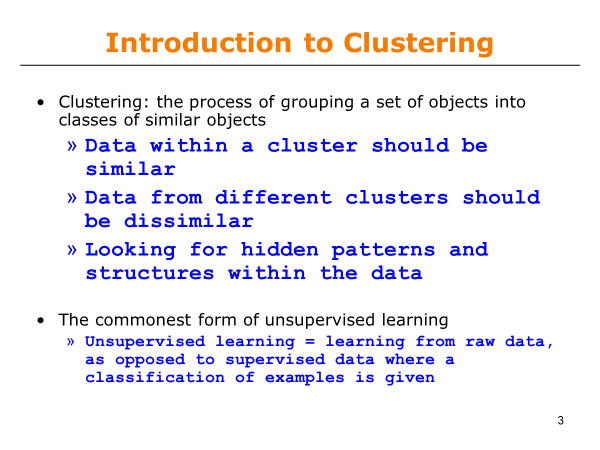

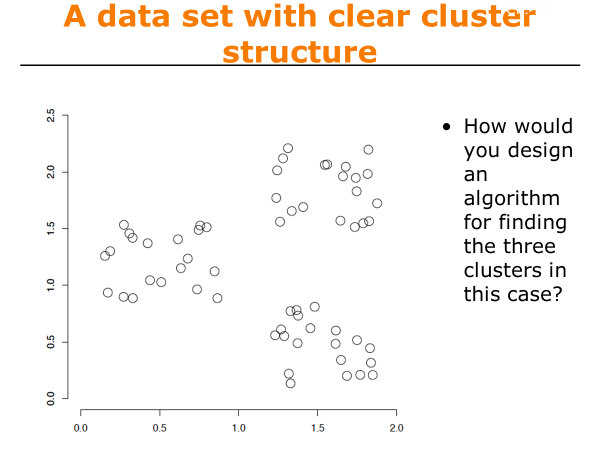

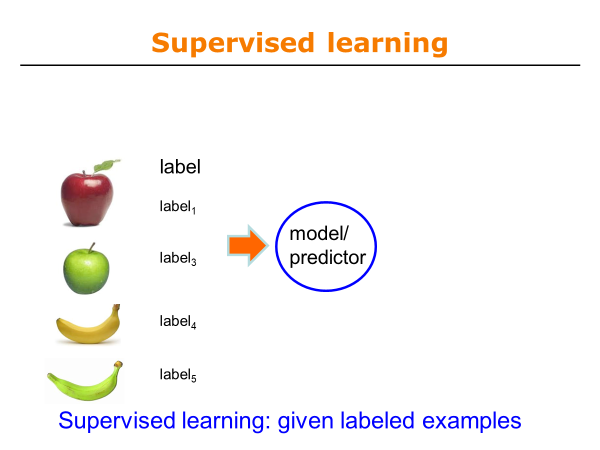

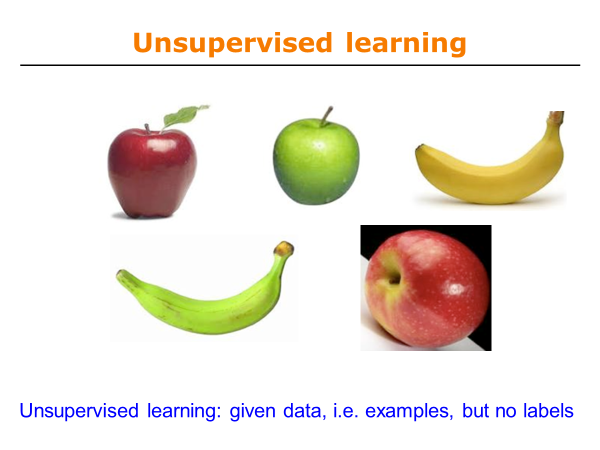

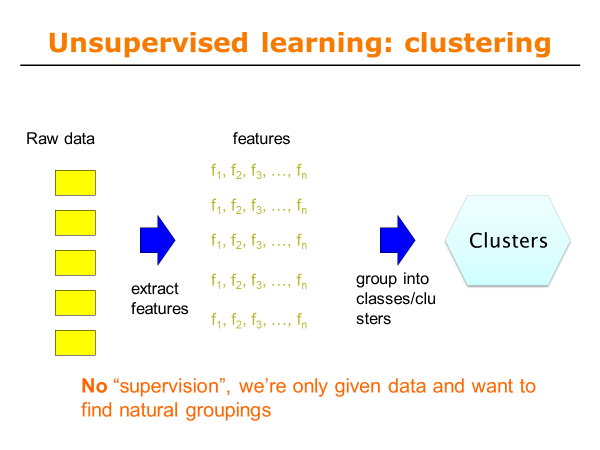

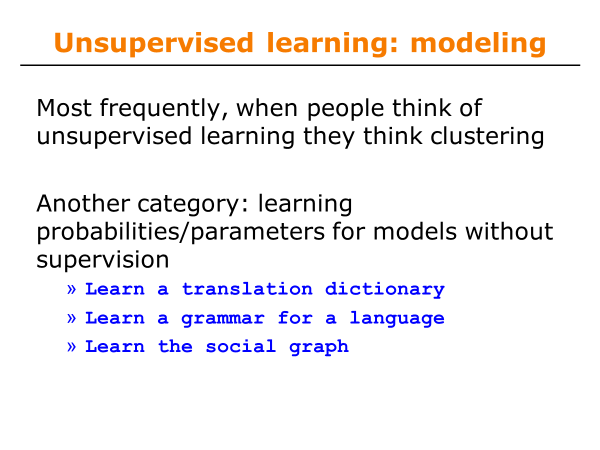

## Clustering Example using k-means

## In-Class#7b

load fisheriris
whos

X = meas(:,3:4);  %petal length and widths of Iris's, note this is a double
species = categorical(species);
categories(species)


plot(X(:,1),X(:,2),'k*','MarkerSize',5);
title 'Fisher''s Iris Data';
xlabel 'Petal Lengths (cm)'; 
ylabel 'Petal Widths (cm)';

### k-means Clustering

grp = kmeans(X,3); %k-means with 3 clusters
scatter(X(:,1),X(:,2),30,grp,'filled')